# Tutorial 1: Statistics Module

In this tutorial you will set up your first linear model with BrainStat. To this end, we will load some sample data from the MICS dataset. But before we get started, please note that this tutorial requires that you have BrainStat and all its dependencies installed. For more details see our installation guide. 

Lets have a look at the cortical thickness data and the demographics data. Note that we've defined a function, `pretty_plot`, at the end of this file to make the plots a little prettier when they're embedded inside live scripts. If you run this tutorial outside of a live script you'll want to comment out the `pretty_plot` lines.

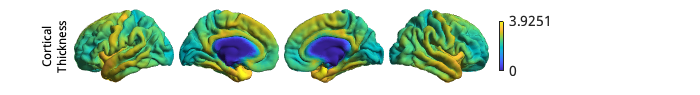

[cortical_thickness, demographics] = fetch_mics_data();
[surf_left, surf_right] = fetch_template_surface('fsaverage5');
surface = fetch_template_surface('fsaverage5', 'join', true);

obj = plot_hemispheres(...
    mean(cortical_thickness)',  ...
    {surf_left, surf_right}, ...
    'labeltext', {{'Cortical', 'Thickness'}} ...
    );
pretty_plot(obj);

disp(demographics(1:10,:))

      SUB_ID      VISIT    AGE_AT_SCAN     SEX 
    __________    _____    ___________    _____

    {'031404'}      1       -0.57968      {'F'}
    {'04a144'}      1       -0.81212      {'M'}
    {'0b78f1'}      1        0.11764      {'M'}
    {'0d26b9'}      1        0.46629      {'F'}
    {'1988b8'}      1        -0.1148      {'M'}
    {'219baf'}      1        -1.0446      {'M'}
    {'242357'}      1        -0.6959      {'F'}
    {'26899f'}      1       -0.92833      {'M'}
    {'26899f'}      2        -0.6959      {'M'}
    {'29b77c'}      1        -1.0446      {'F'}



for ii = 1:2
    fprintf(['Visit %d: N=%d, %d females, mean subject age: %2.2f, ' ...
        'standard deviation of age: %2.2f.\n'], ...
    ii, ...
    sum(demographics.VISIT==ii), ...
    sum(demographics.SEX(demographics.VISIT==ii) == "F"), ...
    mean(demographics.AGE_AT_SCAN(demographics.VISIT==ii)), ...
    std(demographics.AGE_AT_SCAN(demographics.VISIT==ii)));
end

Visit 1: N=70, 30 females, mean subject age: -0.02, standard deviation of age: 1.03.
Visit 2: N=12, 5 females, mean subject age: 0.09, standard deviation of age: 0.87.


Demographics contains four variables: a subject ID, a visit number (some subjects visited multiple times), their age at the time of scanning and their sex. We've also printed the means and standard deviations for visits 1, 2, and both. Next, we will assess whether a subject's age is related to their cortical thickness. To this end we can create a linear model with BrainStat. For our first model, we will only consider the effect of age, i.e. we will disregard the effect of sex and that some subjects visit twice.

### A basic model

term_age = FixedEffect(demographics.AGE_AT_SCAN, 'Age');
model = term_age;
disp(model)

  82×2 FixedEffect array with properties:

     names: ["intercept"    "Age"]
    matrix: [82×2 double]



As you can see, model contains two properties: the names of each variable and a matrix containing the effects in a observation-by-variable matrix. As you can see, an intercept is included in the model by default. We can also access the vectors related to each effect by their name i.e. `model.intercept` and `model.Age `will return the vectors of the intercept and age, respectively.

Next, we must define a contrast in observations (here: age). With the model, contrast, and cortical thickness data, we can then assess whether there is an effect of age on cortical thickness. 

contrast_age = demographics.AGE_AT_SCAN;
mask = fetch_mask('fsaverage5');

slm = SLM( ...
    model, ...
    contrast_age, ...
    'surf', 'fsaverage5', ...
    'correction', {'rft', 'fdr'}, ...
    'cluster_threshold', 0.01, ...
    'mask', mask);
slm.fit(cortical_thickness);


We can access the outcome of this model through its properties. Lets plot the t-values, as well as the peak and cluster p-values derived from a random field theory correction. We've defined a function for slm results at the end of this file as we'll be doing this a lot. 

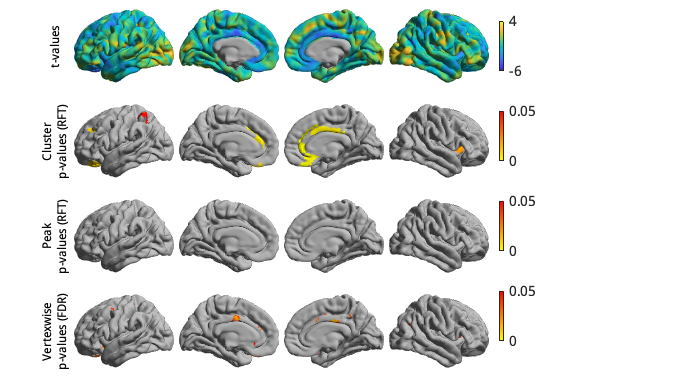

plot_slm(slm, {surf_left, surf_right}, mask, true, true);

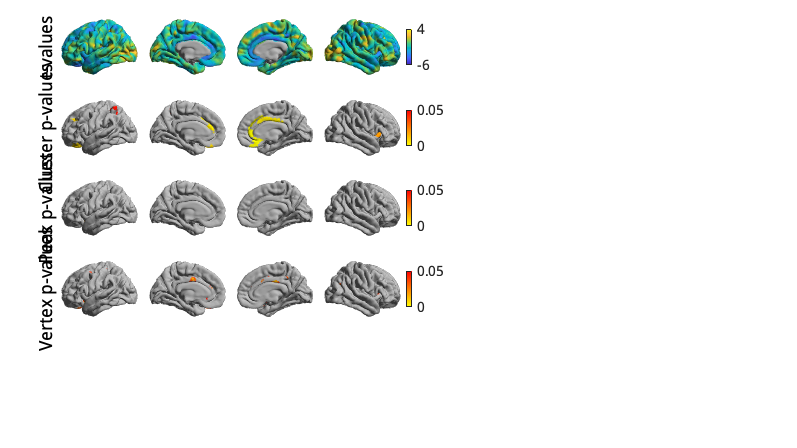

to_plot = [slm.t', slm.P.pval.C', slm.P.pval.P', slm.Q'];
to_plot(~mask, :) = inf; 

obj = plot_hemispheres(to_plot, {surf_left, surf_right}, ...
    'LabelText', {'t-values', 'Cluster p-values', ...
    'Peak p-values', 'Vertex p-values'});
obj.colorlimits([-6, 4; 0, 0.05; 0, 0.05; 0, 0.05])
obj.colormaps({[parula; 0.7, 0.7, 0.7], ...
               [flipud(autumn); 0.7, 0.7, 0.7], ... 
               [flipud(autumn); 0.7, 0.7, 0.7], ...
               [flipud(autumn); 0.7, 0.7, 0.7]});

Only clusters are significant, and not peaks. This suggests that the age effect covers large regions, rather than local foci. Furthermore, at the vertex level we only find few small groups of significant vertices. Lets have a closer look at the clusters and their peaks. The data on clusters are stored in tables inside slm.P.clus and information on the peaks is stored in slm.P.peak. If a two-tailed test is run (BrainStat defaults to two-tailed), a table is returned for each tail. The first table uses the contrast as provided, the second table uses the inverse contrast. If a one-tailed test is performed, then only a single table is returned. Lets print the first 15 rows of the inverted contrast cluster table. 

disp(slm.P.clus{2}(1:15, :))

    clusid    nverts    resels        P     
    ______    ______    ______    __________

       1       141      6.2833    3.3424e-05
       2        82      3.9945      0.001858
       3        69      3.8717     0.0023617
       4        61      3.6705     0.0035174
       5        82      3.6523     0.0036477
       6        70      3.1277      0.010638
       7        49      2.7576      0.023227
       8        62      2.4526      0.044851
       9        42      2.4264      0.047482
      10        47      2.3414      0.057146
      11        41      2.2456      0.070458
      12        43      1.9359        0.1386
      13        34      1.7405       0.21092
      14        28      1.6818       0.23867
      15        33      1.6255       0.26823



Here, we see that cluster 1 contains 141 vertices. Furthermore, we see that clusters 1-9 are significant P<0.05. Lets now have a look at the peaks within these clusters. 

disp(slm.P.peak{2}(1:15, :))

      t       vertid    clusid        P               yeo7        
    ______    ______    ______    _________    ___________________

    5.6954    18720       11      0.0012475    "Ventral Attention"
    5.1648     5430       12       0.009035    "Default"          
    4.8555    16911        6       0.027242    "Ventral Attention"
     4.834    19629        2       0.029335    "Frontoparietal"   
    4.6283    12603       14       0.059519    "Default"          
    4.4789     8454       10       0.098333    "Ventral Attention"
    4.4751     2169        3       0.099588    "Default"          
     4.431     1286       16         0.1152    "Ventral Attention"
    4.3839     9060        3        0.13441    "Default"          
    4.2564    16489        2        0.20282    "Ventral Attention"
    4.1685    15263      

We are able to detect several peaks. The peak with the highest t-statistic (t=5.6954) occurs at vertex 18720, which is inside the ventral attention network as defined by the Yeo-7 networks. However, this peak occurs inside a non-significant cluster (11). Note that the Yeo network membership is only provided if the surface is specified as a template name as we did here. For custom surfaces, or pre-loaded surfaces (as we will use below) this column is omitted. 

### Interaction models

Similarly to age, we can also test for the effect of sex on cortical thickness.

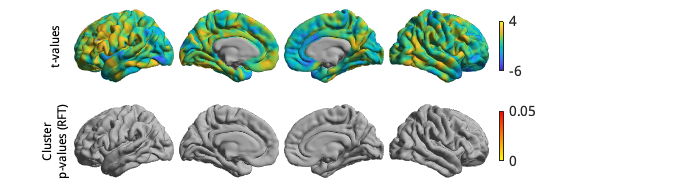

term_sex = FixedEffect(demographics.SEX);
model_sex = term_sex;
contrast_sex = (demographics.SEX == "M") - (demographics.SEX == "F");

slm_sex = SLM( ...
    model_sex, ...
    contrast_sex, ...
    'surf', surface, ...
    'correction', {'rft', 'fdr'}, ...
    'cluster_threshold', 0.01, ...
    'mask', mask);
slm_sex.fit(cortical_thickness);
plot_slm(slm_sex, {surf_left, surf_right}, mask);

Here, we find no significant effects of sex on cortical thickness. However, as we've already established, age has an effect on cortical thickness. So we may want to correct for this effect before evaluating whether sex has an effect on cortical thickenss. Lets make a new model that includes the effect of age.

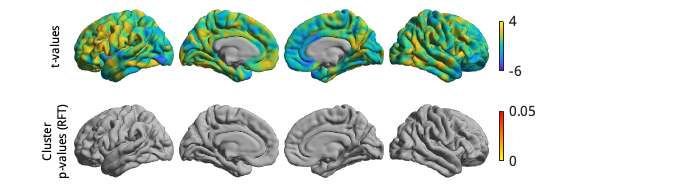

model_sexage = term_age + term_sex;

slm_sexage = SLM( ...
    model_sexage, ...
    contrast_sex, ...
    'surf', surface, ...
    'correction', {'rft', 'fdr'}, ...
    'cluster_threshold', 0.01, ...
    'mask', mask);
slm_sexage.fit(cortical_thickness);
plot_slm(slm_sexage, {surf_left, surf_right}, mask);

After accounting for the effect of age, we still don't find significant clusters of effect of sex on cortical thickness. However, it could be that age affects men and women differently. To account for this, we could include an interaction effect into the model. Lets run the model again with an interaction effect.

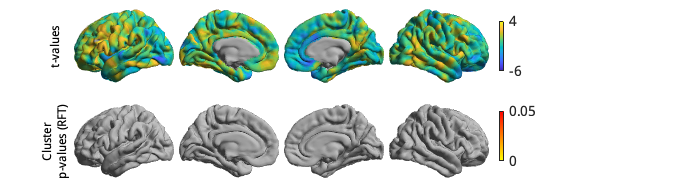

model_sexage_int = term_age + term_sex + term_age * term_sex;

slm_sexage = SLM( ...
    model_sexage_int, ...
    contrast_sex, ...
    'surf', surface, ...
    'correction', {'rft', 'fdr'}, ...
    'cluster_threshold', 0.01, ...
    'mask', mask);
slm_sexage.fit(cortical_thickness);
plot_slm(slm_sexage, {surf_left, surf_right}, mask);

After including the interaction effect, we now do find significant effects of sex on cortical thickness in several clusters. 

Instead of looking at the effects of age or sex, we could also look at whether the cortex of men and women changes differently with age by comparing their interaction effects. To do this, we have to modify the contrast. 

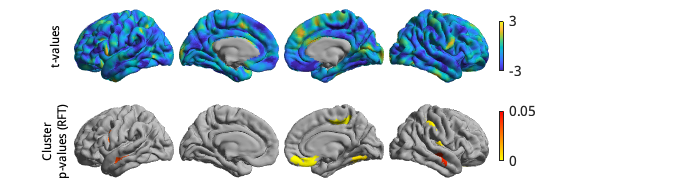

contrast_sex_int = (demographics.AGE_AT_SCAN .* ...
                    (demographics.SEX == "M")) - ...
                   (demographics.AGE_AT_SCAN .* ...
                   (demographics.SEX == "F"));

slm_sexage_int = SLM( ...
    model_sexage_int, ...
    contrast_sex_int, ...
    'surf', surface, ...
    'correction', 'rft', ...
    'cluster_threshold', 0.01, ...
    'mask', mask);
slm_sexage_int.fit(cortical_thickness);

obj = plot_slm(slm_sexage_int, {surf_left, surf_right}, mask);
obj.colorlimits([-3, 3; 0, 0.05]);

Indeed, it appears that the interaction effect between sex and age is quite different across men and women, with stronger effects occuring in women. 

### One-tailed models

Imagine that, based on prior research, we hypothesize that men have higher cortical thickness than women. In that case, we could run this same model with a one-tailed test, rather than a two-tailed test. By default BrainStat uses a two-tailed test. If you want to get a one-tailed test, simply specify it in the SLM model initialization with `'two_tailed', false`. Note that the one-tailed test will test for the significance of positive t-values. If you want to test for the significance of negative t-values, simply change the sign of the contrast. We may hypothesize based on prior research that cortical thickness decreases with age, so we could specify this as follows. Note the minus in front of `contrast_age` to test for decreasing thickness with age.

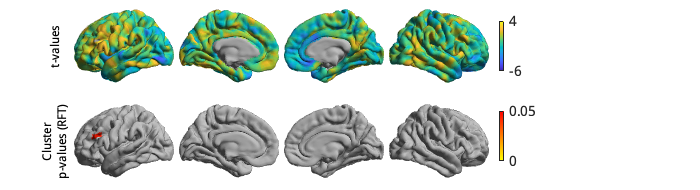

slm_onetail = SLM( ...
    model_sexage_int, ...
    contrast_sex, ...
    'surf', surface, ...
    'correction', {'rft', 'fdr'}, ...
    'cluster_threshold', 0.01, ...
    'two_tailed', false, ...
    'mask', mask);
slm_onetail.fit(cortical_thickness);
plot_slm(slm_onetail, {surf_left, surf_right}, mask);

Notice the additional clusters that we find when using a one-tailed test.

### Mixed Effects Models

So far, we've considered multiple visits of the same subject as two separate, independent measurements. Clearly, however, such measurements are not independent of each other. To account for this, we could add subject ID as a random effect. Lets do this and test the effect of age on cortical thickness again.

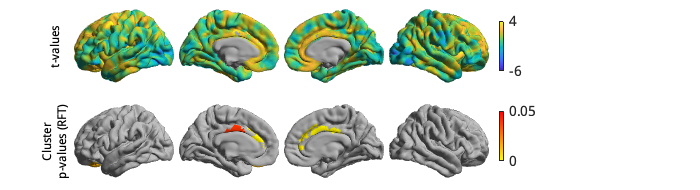

term_subject = MixedEffect(demographics.SUB_ID);
model_mixed = term_age + term_sex + term_age * term_sex + term_subject;

slm_mixed = SLM( ...
    model_mixed, ...
    -contrast_age, ...
    'surf', surface, ...
    'correction', 'rft', ...
    'cluster_threshold', 0.01, ...
    'two_tailed', false, ...
    'mask', mask);
slm_mixed.fit(cortical_thickness);

obj = plot_slm(slm_mixed, {surf_left, surf_right}, mask);
obj.colorlimits([-6, 4; 0, 0.05]);

After inclusion of subject as a random variable into the one-tailed model shown earlier, we find fewer and smaller clusters, indicating that by not accounting for the repeated measures structure of the data we were overestimating the significance of effects.

That concludes the basic usage of the BrainStat for statistical models. In the next tutorial we'll show you how to use the context decoding module.

Below are the support functions used in this live script. 

function pretty_plot(obj)
% Makes the BrainSpace plots prettier inside live scripts.
obj.handles.figure.Units = 'pixels';
set(obj.handles.axes, 'Units', 'pixels')
set(obj.handles.colorbar, 'Units', 'pixels');
obj.handles.figure.Position = [1, 1, 700, size(obj.data, 2) * 95];
set(obj.handles.text, 'FontSize', 12);

for jj = 1:size(obj.data, 2) % variates
    obj.handles.colorbar(jj).Position = [...
        500, ...
        30 + (size(obj.data, 2) * 95) - 10 - jj*90, ...
        5, ...
        50];
    for ii = 1:4 % views
        obj.handles.axes(jj, ii).Position = [...
            75 + (ii-1)*105, ...
            (size(obj.data, 2) * 95) - jj*95, ...
            100, ...
            100];
    end
end
end

function obj = plot_slm(slm, surfaces, mask, plot_peak, plot_fdr)
% Plot the t-values and p-values of an SLM.
arguments
    slm
    surfaces
    mask
    plot_peak (1,1) logical = false
    plot_fdr (1,1) logical = false
end

to_plot = [slm.t(:), slm.P.pval.C(:)];
labels = {'t-values', {'Cluster', 'p-values (RFT)'}};
colormaps = {[parula; .7 .7 .7];
    [flipud(autumn); .7 .7 .7]};
colorlimits = [-6, 4; 0, 0.05];

if plot_peak
    to_plot = [to_plot, slm.P.pval.P(:)];
    labels = [labels, {{'Peak', 'p-values (RFT)'}}];
    colormaps = [colormaps; {[flipud(autumn); .7 .7 .7]}];
    colorlimits = [colorlimits; 0, 0.05];
end

if plot_fdr
    to_plot = [to_plot, slm.Q(:)];
    labels = [labels, {{'Vertexwise', 'p-values (FDR)'}}];
    colormaps = [colormaps; {[flipud(autumn); .7 .7 .7]}];
    colorlimits = [colorlimits; 0, 0.05];
end

to_plot(~mask, :) = inf;

obj = plot_hemispheres(...
    to_plot,  ...
    {surfaces{1}, surfaces{2}}, ...
    'labeltext', labels ...
    );

obj.colormaps(colormaps);
obj.colorlimits(colorlimits);
pretty_plot(obj);
end